# LiDARDRONE

# Drone Control with pid dynamics

MRK 1.2

This file correspond to a single iteration of a single drone during its simulation

clc;
clear;
clear all;
clf;

#### Map definition and obstacles plot

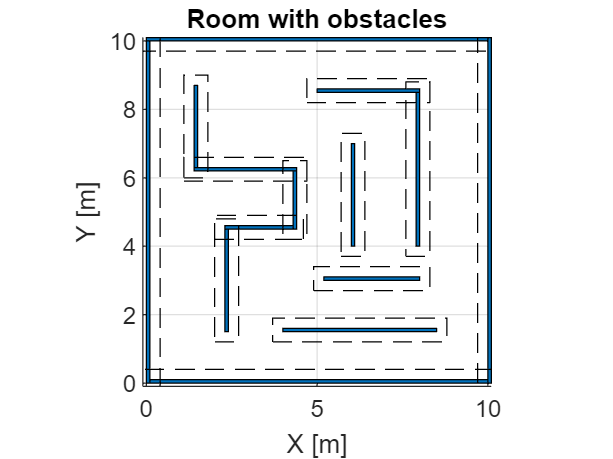

x_map_size = 10;
y_map_size = 10;

[obstacles, inflated_obstacles] = map_definition;

figure();
grid on;
axis equal; 
xlabel('X [m]');
ylabel('Y [m]');
xlim([-0.10 x_map_size + 0.1]);
ylim([-0.10 y_map_size + 0.1]);
title('Room with obstacles');
PLOT_MAP(obstacles, inflated_obstacles, 10, 10);

#### Build the RRT algorith to explore the space (ONE STEP TIME EXAMPLE)

% Parameter declaration
step_size = 0.3; 
n_iterations = 10; 
% goal_threshold = 0.5; 

% RRT initialization

start = [rand() * x_map_size, rand() * y_map_size]; % absolute poi from wich the drone starts the simulation

[rrt_tree, rrt_relative_tree, parent_indices, start] = RRT_DRONE(step_size,n_iterations, inflated_obstacles,  x_map_size,  y_map_size, start);

#### Plot the RRT

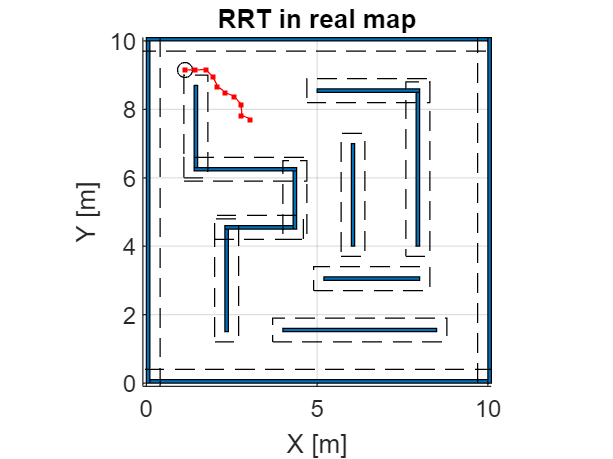

figure();
grid on;
axis equal; 
xlabel('X [m]');
ylabel('Y [m]');
xlim([-0.10 x_map_size + 0.1]);
ylim([-0.10 y_map_size + 0.1]);
title('RRT in real map');
hold on;
PLOT_MAP(obstacles, inflated_obstacles, 10, 10);
RRT_PLOT(rrt_tree, parent_indices);
hold off;

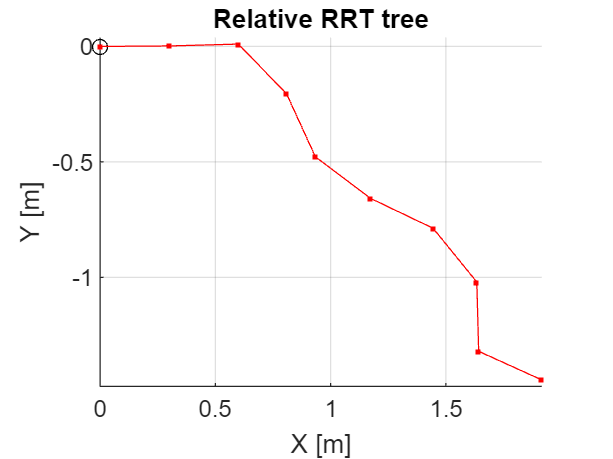


figure();
grid on;
axis equal; 
xlabel('X [m]');
ylabel('Y [m]');
title('Relative RRT tree');
RRT_PLOT(rrt_relative_tree, parent_indices);

## LiDAR test example

% lidar_position = start;
% lidar_angles = linspace(0, 360, 100);  % 100 scanning lines
% max_range = 2;
% lidar_dist_res = 0.01; 
% [point_abs,point_abs_clean, point_rel, dist_rel] = Lidar_scan(obstacles, lidar_position, lidar_angles, max_range, lidar_dist_res);

Plot Lidar example

% figure();
% % Plot obstacles
% for i = 1:size(obstacles, 1)
%     hold on
%     rectangle('Position', obstacles(i, :), 'FaceColor', '#0072BD');
% end
% % Plot inflated obstacles
% for i = 1:size(inflated_obstacles, 1)
%     rectangle('Position', inflated_obstacles(i, :), 'EdgeColor', 'k', 'LineStyle', '--');
% end
% % Plot LiDAR result
% for angle_step = 1:length(lidar_angles)-1
%     angle = lidar_angles(angle_step);
%     ray_direction = [cosd(angle), sind(angle)];
%     hit_point = point_abs(angle_step, :);
%     if ~all(hit_point == 0) % Plot just hit point_path
% 
%         plot([lidar_position(1), hit_point(1)], [lidar_position(2), hit_point(2)],'LineStyle', ':', 'Color', 'red', 'Marker' , "."'); % Plot ray
%     end
% end
% grid on;
% axis equal; 
% xlabel('X [m]');
% ylabel('Y [m]');
% xlim([-0.10 x_map_size + 0.1]);
% ylim([-0.10 y_map_size + 0.1]);
% title('Lidar Test');
% hold off;
% 
% % Plot LiDAR result in relative envioment
% plot(point_rel(:, 1), point_rel(:, 2), 'o', 'MarkerFaceColor', 'r', 'MarkerEdgeColor', 'black', 'MarkerSize', 5); % Plot ray
% grid on;
% axis equal; 
% xlabel('X [m]');
% ylabel('Y [m]');
% title('Lidar Relative point position');
% 
% 
% img = imread('drone.jpg'); % Sostituisci con il percorso dell'immagine
% imageWidth = 0.5; % Larghezza desiderata dell'immagine
% imageHeight = 0.5; % Altezza desiderata dell'immagine
% xPos = 0 - imageWidth/2; % Posizionamento sull'asse x
% yPos = 0 - imageHeight/2; % Posizionamento sull'asse y
% 
% % Aggiungi l'immagine alla posizione specificata
% image('CData', img, 'XData', [xPos, xPos + imageWidth], 'YData', [yPos, yPos + imageHeight]);


#### PID navigation

% Identify the farest point wrt the tree generated in the lidar reference
% frame
farest = [0; 0];
dist_farest = 0;
for k=2:length(rrt_relative_tree)
    temp_point = rrt_relative_tree(k, :);
    if norm(rrt_relative_tree(1, :) - rrt_relative_tree(k, :)) > dist_farest
        dist_farest = norm(rrt_relative_tree(1, :) - rrt_relative_tree(k, :));
        farest = rrt_relative_tree(k, :);
    end
end
correspondence = ismember(rrt_relative_tree, farest, 'rows');
index = find(all(correspondence, 2));
% reconstruct the path to make

#### Reconstruction of the path to reach the farest point

points_rrt = [];
while index ~= 0
    points_rrt = [rrt_relative_tree(index, :); points_rrt];
    index = parent_indices(index);
end

points = points_rrt';

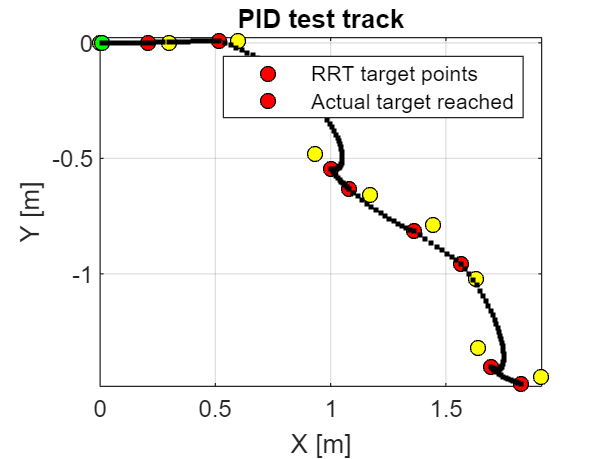

% Coefficienti PID -- METTERE IN FUNZIONE
Kp = 0.6; % componente proporzionale
Ki = 0.02; % componente integrale
Kd = 0.9; % componente derivativa

% Error variables
error_sum=0;
previous_error = 0;

final_pos = points(:, length(points));
% Velocità iniziale e finale desiderate
initial_vel = [0; 0];
max_speed = [1; 1]; % velocità massima consentita
final_vel = max_speed/2; % velocità finale desiderata
% Simulazione del controllo PID
t = 0; % tempo iniziale
positions = []; % registro delle posizioni per la visualizzazione
% Passo temporale (in secondi)
dt = 0.1;

% Posizione iniziale del punto
pos = points(:, 1);

% Velocità iniziale del punto
vel = initial_vel;

% continua finché non si raggiunge la destinazione

proximity_threshold = 0.1;
figure();
for i=2:length(points)

    % momentaneous target of the drone where it has to go
    final_pos = points(:, i);

    while norm(pos - final_pos) > proximity_threshold  
        % Calcolo dell'errore di posizione
        error_pos = final_pos - pos;

        % Componente proporzionale
        control_p = Kp * error_pos;

        % Componente integrale
        error_sum = error_sum + error_pos * dt;
        control_i = Ki * error_sum;

        % Componente derivativa
        derivative = (error_pos - previous_error) / dt;
        control_d = Kd * derivative;

        % Controllo finale
        control = control_p + control_i + control_d;

        % Limitazione della velocità
        control = min(max(control, -max_speed), max_speed);

        % Aggiornamento della velocità e della posizione
        vel = vel + control * dt;
        pos = pos + vel * dt;

        % Memorizzazione della posizione
        positions = [positions, pos];

        % Aggiornamento dell'errore precedente
        previous_error = error_pos;

        t = t + dt; % incremento del tempo
    end

    %Visualize the time requested and error
    % t
    % vel(length(vel))
    % pos(length(pos))
    % error_pos(length(error_pos))
    plot(positions(1, length(positions)), positions(2, length(positions)), 'o', 'MarkerFaceColor', 'red', 'MarkerEdgeColor', 'black');
    hold on;
    %plot the end point
end


plot(points(1, :), points(2, :), 'o', 'MarkerFaceColor', 'yellow', 'MarkerEdgeColor', 'black')
grid on;
axis equal; 

% Visualizzazione del percorso
%starting point in red
plot(positions(1, 1), positions(2, 1), 'o', 'MarkerFaceColor', 'green', 'MarkerEdgeColor', 'black');
%plot the path
plot(positions(1, :), positions(2, :), '.', 'Color', 'black');
%ending point in black


xlabel('X [m]');
ylabel('Y [m]');
title('PID test track');
hold off
legend('RRT target points', 'Actual target reached');

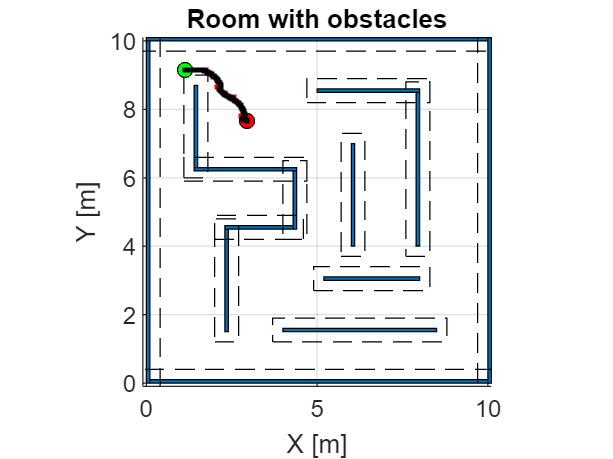

% plot all in the absolute ref frame
figure();
grid on;
axis equal; 
xlabel('X [m]');
ylabel('Y [m]');
xlim([-0.10 x_map_size + 0.1]);
ylim([-0.10 y_map_size + 0.1]);
title('Room with obstacles');
PLOT_MAP(obstacles, inflated_obstacles, 10, 10);
hold on;
RRT_PLOT(rrt_tree, parent_indices);
plot(positions(1, 1) + start(1, 1) , positions(2, 1) + start(1, 2), 'o', 'MarkerFaceColor', 'g', 'MarkerEdgeColor', 'black');
plot(positions(1, length(positions)) + start(1, 1), positions(2, length(positions)) + start(1, 2), 'o', 'MarkerFaceColor', 'r', 'MarkerEdgeColor', 'black');
plot(positions(1, :) + start(1, 1), positions(2, :) + start(1, 2), '.', 'Color', 'black');
hold off;